**Analytical Method of Solving for System Response**

alpha = -1/6; beta = sqrt(23)/6; %solution constants. these were solved using a quadratic equation
C1 = 0; %calculated analytically
C2 = 3 * sqrt(23) / 46; %calculated analytically
t1 = [0:0.1:25];

xAnalytical = exp(alpha .* t1) .* (C1.*cos(beta .* t1) + C2.*sin(beta .* t1));

**Euler's Method of Solving for System Response**

m = 3; c = 1; k = 2; %constants of the system
dt = 0.01; %time step
tf = 25; %final time
stop = tf/dt; %number of iterations
t2 = zeros(1,stop);
xEuler = zeros(2,stop);
xEuler(1,1) = 0; xEuler(2,1) = .25; t2(1) = 0; %initial conditions
x0 = xEuler(1,1); v0 = xEuler(2,1);
wn = sqrt(k/m); %natural frequency
zeta = c/(2*sqrt(k*m)); %damping ratio

for ii = 1:stop
    xEuler(1,ii+1) = xEuler(1,ii) + dt * xEuler(2,ii); %displacement vector
    xEuler(2,ii+1) = xEuler(2,ii) + (-wn^2 * xEuler(1,ii) - 2 * zeta * wn * xEuler(2,ii))*dt; %velocity vector
    t2(ii+1) = t2(ii) + dt; %time vector
end

**ODE45 Method of Solving for System Response**

IC = [x0 v0];
[t3,xODE] = ode45(@f_sdof,t2,IC);

**Plots**

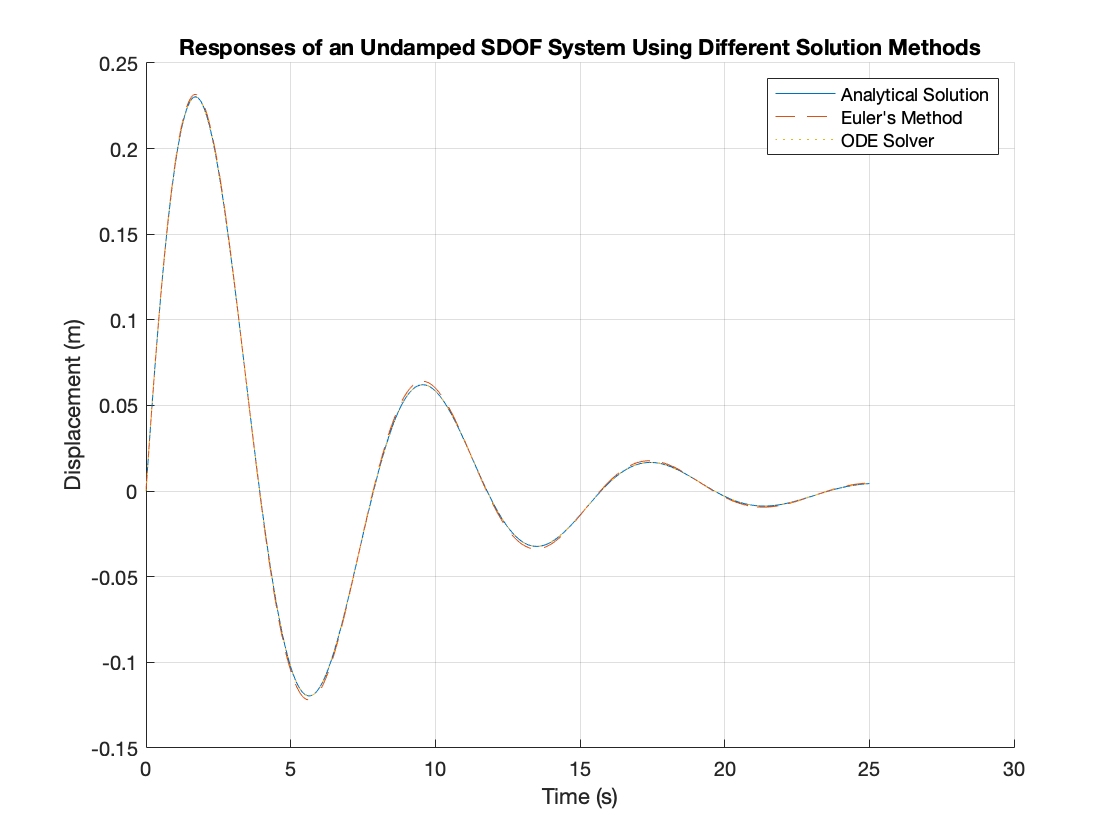

hold on
grid
plot(t1,xAnalytical,'-')
plot(t2,xEuler(1,:),'--')
plot(t3,xODE(:,1),':')
legend('Analytical Solution',"Euler's Method",'ODE Solver')
xlabel('Time (s)')
ylabel('Displacement (m)')
title('Responses of an Undamped SDOF System Using Different Solution Methods')

**Function**

function xdot = f_sdof(t,x)
xdot = zeros(2,1);
xdot(1) = x(2);
xdot(2) = (-2/3)*x(1)-(1/3)*x(2);
end